clc
clear all

## Loaded Data:

% Load Lap 1 data from the file
lap1Data = load('Lap1_data.mat');

% Access the variables from the structure
lap1LAT = lap1Data.lap1LAT;
lap1LONG = lap1Data.lap1LONG;
lap1Velocity = lap1Data.lap1Velocity;
lap1AccX_smooth = lap1Data.lap1AccX_smooth;
lap1AccY_smooth = lap1Data.lap1AccY_smooth;

% Calculate the array for Lap 1
numPointsLap1 = length(lap1LAT);
lap1DataArray = zeros(numPointsLap1, 5);  % Columns are LAT, LONG, Velocity, MaxAccX, MaxAccY

% Iterate over each point
for i = 1:numPointsLap1
    lap1DataArray(i, :) = [lap1LAT(i), lap1LONG(i), lap1Velocity(i), lap1AccX_smooth(i), lap1AccY_smooth(i)];
end

% Remove duplicates and retain the maximum accY value
[uniqueCoords, ~, idx] = unique(lap1DataArray(:, 1:2), 'rows', 'stable');
minAccY = accumarray(idx, lap1DataArray(:, 5), [], @min);
filteredLap1Data = [uniqueCoords, zeros(size(uniqueCoords, 1), 3)];
for i = 1:size(uniqueCoords, 1)
    relevantIdx = lap1DataArray(:, 1) == uniqueCoords(i, 1) & lap1DataArray(:, 2) == uniqueCoords(i, 2) & lap1DataArray(:, 5) == minAccY(i);
    filteredLap1Data(i, 3:5) = lap1DataArray(relevantIdx, 3:5);
end

% Similarly, load and process Lap 2 data
lap2Data = load('Lap2_data.mat');
lap2LAT = lap2Data.lap2LAT;
lap2LONG = lap2Data.lap2LONG;
lap2Velocity = lap2Data.lap2Velocity;
lap2AccX_smooth = lap2Data.lap2AccX_smooth;
lap2AccY_smooth = lap2Data.lap2AccY_smooth;

% Calculate the array for Lap 2
numPointsLap2 = length(lap2LAT);
lap2DataArray = zeros(numPointsLap2, 5);  % Columns are LAT, LONG, Velocity, MaxAccX, MaxAccY

% Iterate over each point
for i = 1:numPointsLap2
    lap2DataArray(i, :) = [lap2LAT(i), lap2LONG(i), lap2Velocity(i), lap2AccX_smooth(i), lap2AccY_smooth(i)];
end

% Remove duplicates and retain the maximum accY value
[uniqueCoords2, ~, idx2] = unique(lap2DataArray(:, 1:2), 'rows', 'stable');
minAccY2 = accumarray(idx2, lap2DataArray(:, 5), [], @min);
filteredLap2Data = [uniqueCoords2, zeros(size(uniqueCoords2, 1), 3)];
for i = 1:size(uniqueCoords2, 1)
    relevantIdx2 = lap2DataArray(:, 1) == uniqueCoords2(i, 1) & lap2DataArray(:, 2) == uniqueCoords2(i, 2) & lap2DataArray(:, 5) == minAccY2(i);
    filteredLap2Data(i, 3:5) = lap2DataArray(relevantIdx2, 3:5);
end

## Losses 1-Tyre Model:

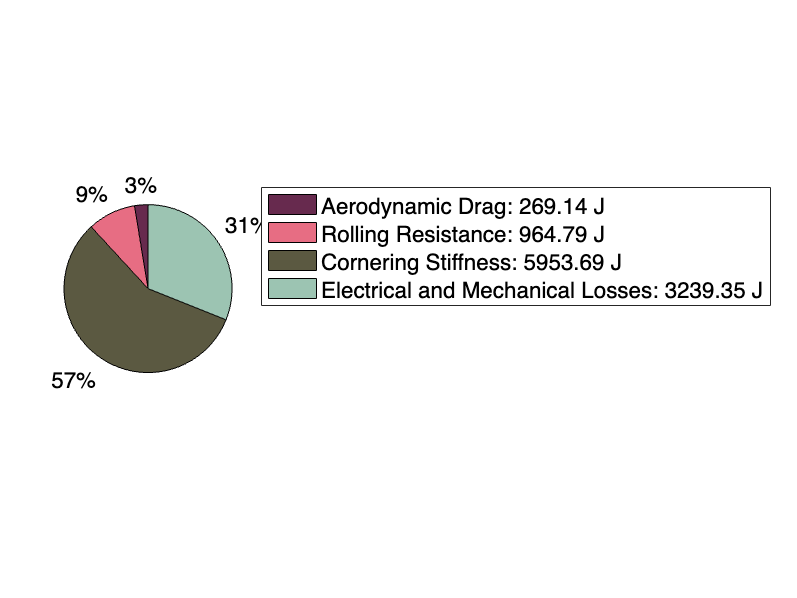

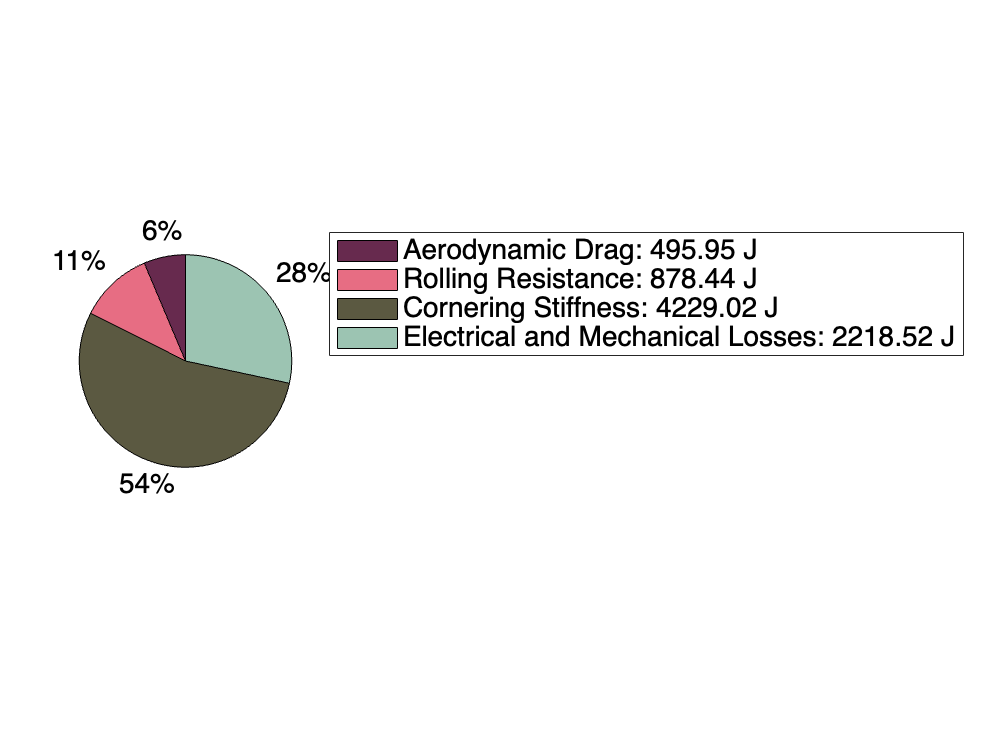

% Constants and setup
g = 9.81; % gravitational acceleration (m/s^2)
md = 50; % driver mass (kg)
mc = 46; % car mass (kg)
earth_radius = 6371000; % (m)
W = (mc + md) * g; % total weight

% Drag constants
FrontalArea = 0.39; % (m^2)
DragCoefficientAir = 0.112; 
densityAir = 1.293; % (kg/m^3)
Slope = 0; % slope angle in radians

% Tire model constants
CoefCorrneringStiffness80Psi = 0.2210;
CoefCorrneringResistance80Psi = 0.0027;
CorneringStiffness1 = W * CoefCorrneringStiffness80Psi;
RollingResistance1 = W * CoefCorrneringResistance80Psi;

% Corner Definitions
Corner1Entry = 78; % meters
Corner1Exit = 145; % meters
Corner2Entry = 264; % meters
Corner2Exit = 343; % meters

% Assuming filteredLap1Data and filteredLap2Data are loaded
lapsData = {filteredLap1Data, filteredLap2Data};
energyLosses = struct();

% Processing each lap
for lapIdx = 1:2
    lapData = lapsData{lapIdx};
    LAT = lapData(:, 1);
    LONG = lapData(:, 2);
    Velocity = lapData(:, 3);
    AccY = lapData(:, 5);

    numPoints = size(lapData, 1);
    AeroDrag = zeros(numPoints-1, 1);
    TyreDragRolling = zeros(numPoints-1, 1);
    TyreDragCorneringStiffness = zeros(numPoints-1, 1);
    Distance = zeros(numPoints-1, 1);
    CumulativeDistance = zeros(numPoints-1, 1);
    alpha = zeros(numPoints-1, 1);

    % Calculate drag at each point
    for i = 1:numPoints-1
        % Aerodynamic Drag Calculation
        AeroDrag(i) = 0.5 * densityAir * FrontalArea * DragCoefficientAir * ((Velocity(i)+Velocity(i+1)) / 2)^2;

        % Tyre Drag Calculation
        alpha(i) = ((md + mc)*(abs(AccY(i))))/(CorneringStiffness1-RollingResistance1*pi/180);
        if alpha(i) > 0.16;
            alpha(i) = 0.16;
        end
     
        TyreDragRolling(i) = RollingResistance1 * cos(alpha(i));
        TyreDragCorneringStiffness(i) = CorneringStiffness1 * sin(alpha(i));

        % Distance calculation using the Haversine formula
        lat1 = deg2rad(LAT(i));
        lat2 = deg2rad(LAT(i+1));
        lon1 = deg2rad(LONG(i));
        lon2 = deg2rad(LONG(i+1));
        dlat = lat2 - lat1;
        dlon = lon2 - lon1;
        a = sin(dlat/2)^2 + cos(lat1) * cos(lat2) * sin(dlon/2)^2;
        c = 2 * atan2(sqrt(a), sqrt(1-a));
        Distance(i) = earth_radius * c;

        if i == 1
            CumulativeDistance(i) = Distance(i);
        else
            CumulativeDistance(i) = CumulativeDistance(i-1) + Distance(i);
        end
    end

    % Sum energy losses, only including Tyre Drag Cornering Stiffness within specified corners
    energyLosses(lapIdx).AeroDrag = sum(AeroDrag .* Distance);
    energyLosses(lapIdx).TyreDragRolling = sum(TyreDragRolling .* Distance);
    energyLosses(lapIdx).TyreDragCorneringStiffness = sum(TyreDragCorneringStiffness .* Distance .* ...
        ((CumulativeDistance >= Corner1Entry & CumulativeDistance <= Corner1Exit) | ...
         (CumulativeDistance >= Corner2Entry & CumulativeDistance <= Corner2Exit)));
end

% Assuming `energyLosses` is defined properly somewhere in your code
% Load the energy data correctly from the .mat files
lap1Energy = load('Lap1_energy.mat');
lap2Energy = load('Lap2_energy.mat');
lapNumbers = [14 6];

% Assuming that 'energy' is the variable stored in each .mat file
lapsEnergy = zeros(1, 2);
lapsEnergy(1) = lap1Energy.EnergyLap1; % Access the 'energy' field if it's named 'energy' in the .mat file
lapsEnergy(2) = lap2Energy.EnergyLap2; % Same as above

% Define the custom colors in RGB format as MATLAB uses RGB triples
customColors = [hex2rgb('#672A4E');  % Dark reddish-purple
                hex2rgb('#E76D83');  % Soft red
                hex2rgb('#5B5941');  % Olive greenish
                hex2rgb('#9CC4B2')]; % Soft teal

% Generate pie charts with custom colors
for lapIdx = 1:2
    figure; % Create a new figure for each lap
    EnergyLosses = lapsEnergy(lapIdx) - energyLosses(lapIdx).AeroDrag - energyLosses(lapIdx).TyreDragRolling - energyLosses(lapIdx).TyreDragCorneringStiffness;
    energyValues = [energyLosses(lapIdx).AeroDrag, energyLosses(lapIdx).TyreDragRolling, energyLosses(lapIdx).TyreDragCorneringStiffness, EnergyLosses];
    labels = {
        sprintf('Aerodynamic Drag: %.2f J', energyLosses(lapIdx).AeroDrag),
        sprintf('Rolling Resistance: %.2f J', energyLosses(lapIdx).TyreDragRolling),
        sprintf('Cornering Stiffness: %.2f J', energyLosses(lapIdx).TyreDragCorneringStiffness),
        sprintf('Electrical and Mechanical Losses: %.2f J', EnergyLosses)
    };
    
    % Create the pie chart
    p = pie(energyValues);
    % Set text size for the pie chart
    hText = findobj(p, 'Type', 'text');
    set(hText, 'FontSize', 14);
    
    %title(sprintf('Pie Chart of Energy Losses for Lap %d', lapNumbers(lapIdx))); % Set title for each chart
    
    % Apply the custom colors to each slice of the pie chart
    colormap(customColors);
    
    % Add a legend with custom labels
    legend(labels, 'Location', 'bestoutside', 'FontSize', 14); % Set legend text size to 14
end

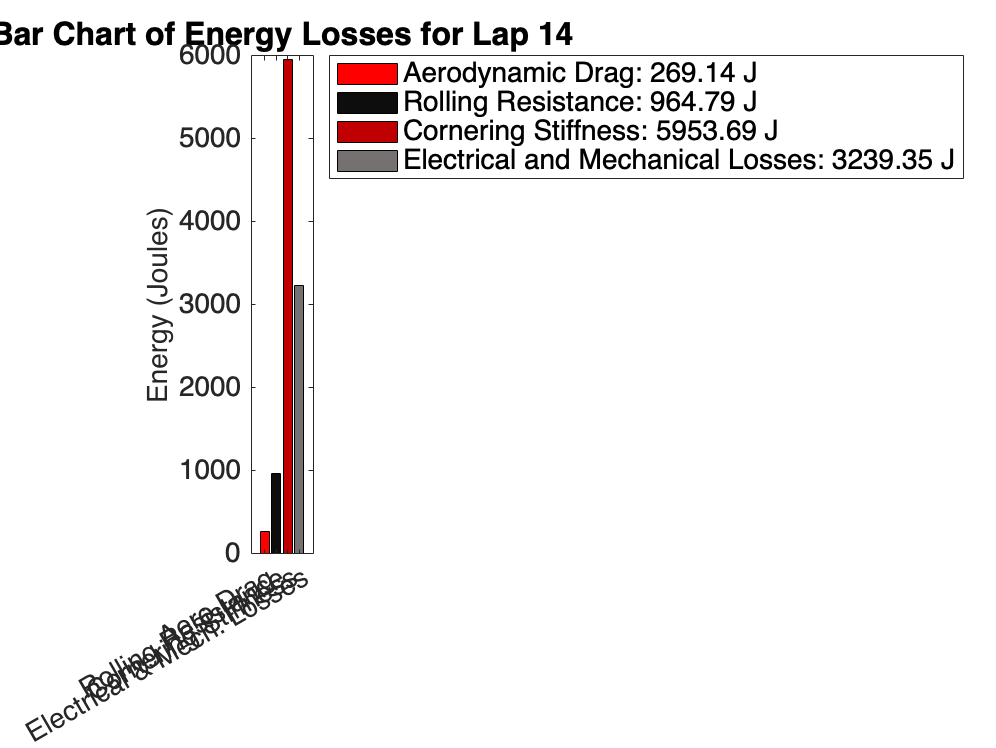

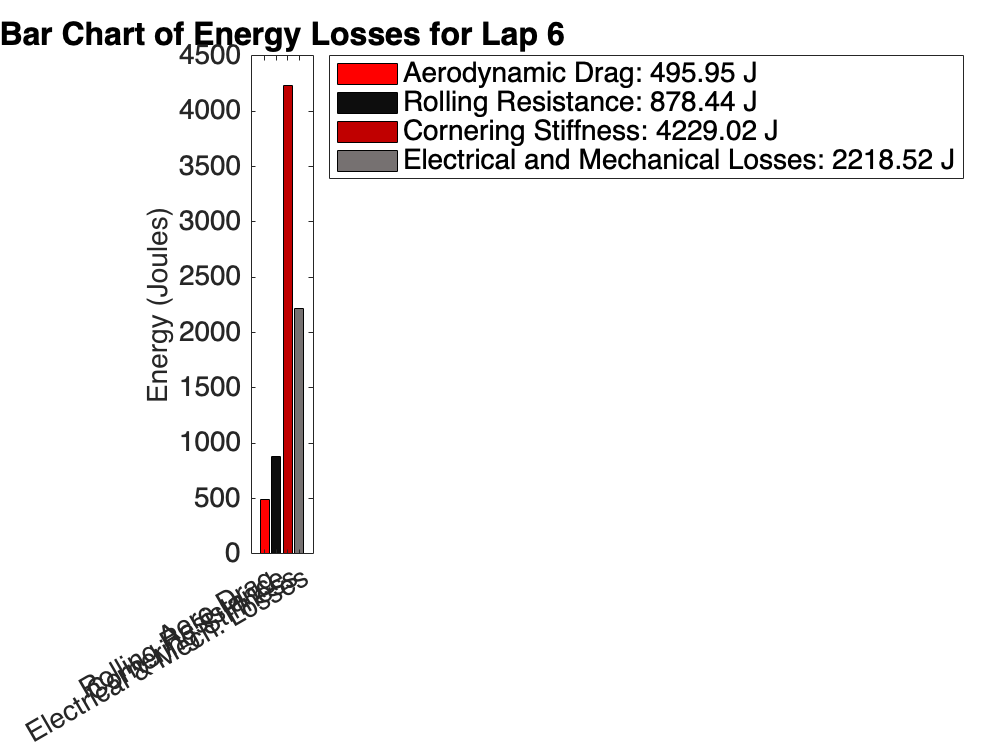


% Load the energy data correctly from the .mat files
lap1Energy = load('Lap1_energy.mat');
lap2Energy = load('Lap2_energy.mat');
lapNumbers = [14 6];

% Assuming that 'energy' is the variable stored in each .mat file
lapsEnergy = zeros(1, 2);
lapsEnergy(1) = lap1Energy.EnergyLap1; % Access the 'energy' field if it's named 'energy' in the .mat file
lapsEnergy(2) = lap2Energy.EnergyLap2; % Same as above

% Define the custom colors in RGB format as MATLAB uses RGB triples
customColors = [hex2rgb('#FF0000');  % Dark reddish-purple
                hex2rgb('#0D0D0D');  % Soft red
                hex2rgb('#C00000');  % Olive greenish
                hex2rgb('#767171')]; % Soft teal

% Generate bar charts with custom colors% Generate bar charts with custom colors
% Generate bar charts with custom colors
for lapIdx = 1:2
    figure; % Create a new figure for each lap
    EnergyLosses = lapsEnergy(lapIdx) - energyLosses(lapIdx).AeroDrag - energyLosses(lapIdx).TyreDragRolling - energyLosses(lapIdx).TyreDragCorneringStiffness;
    energyValues = [energyLosses(lapIdx).AeroDrag, energyLosses(lapIdx).TyreDragRolling, energyLosses(lapIdx).TyreDragCorneringStiffness, EnergyLosses];
    
    % Create the bar chart
    b = bar(energyValues, 'FaceColor', 'flat');
    
    % Apply the custom colors to each bar
    for k = 1:length(energyValues)
        b.CData(k, :) = customColors(k, :);
    end
    
    % Set the x-axis labels
    set(gca, 'XTickLabel', {'Aero Drag', 'Rolling Resistance', 'Cornering Stiffness', 'Electrical & Mech. Losses'}, 'FontSize', 14);
    
    % Set the y-axis label
    ylabel('Energy (Joules)', 'FontSize', 14);
    
    % Set title for each chart
    title(sprintf('Bar Chart of Energy Losses for Lap %d', lapNumbers(lapIdx)), 'FontSize', 16);
    
    % Create a dummy bar graph for the legend
    hold on;
    numCategories = length(energyValues);
    for i = 1:numCategories
        barh = bar(nan, 'FaceColor', customColors(i, :));
        h(i) = barh;  % Collect handles for legend
    end
    hold off;
    
    % Add a legend with custom labels
    labels = {
        sprintf('Aerodynamic Drag: %.2f J', energyLosses(lapIdx).AeroDrag),
        sprintf('Rolling Resistance: %.2f J', energyLosses(lapIdx).TyreDragRolling),
        sprintf('Cornering Stiffness: %.2f J', energyLosses(lapIdx).TyreDragCorneringStiffness),
        sprintf('Electrical and Mechanical Losses: %.2f J', EnergyLosses)
    };
    legend(h, labels, 'Location', 'bestoutside', 'FontSize', 14);
end

function rgb = hex2rgb(hexStr)
    % Convert hex color code to RGB triplet
    hexStr = strrep(hexStr, '#', '');
    rgb = sscanf(hexStr, '%2x%2x%2x', [1 3]) / 255;
end


function [cx, cy, r] = fitCircle(x, y)
    % Simple algebraic circle fit (Kasa method)
    A = [x y ones(length(x), 1)];
    B = -(x.^2 + y.^2);
    sol = A \ B;
    cx = -0.5 * sol(1);
    cy = -0.5 * sol(2);
    r = sqrt((sol(1)^2 + sol(2)^2)/4 - sol(3));
end
